x = readtable('Sample9DoF_R_Session1_Shimmer_B663_Calibrated_SD.csv');

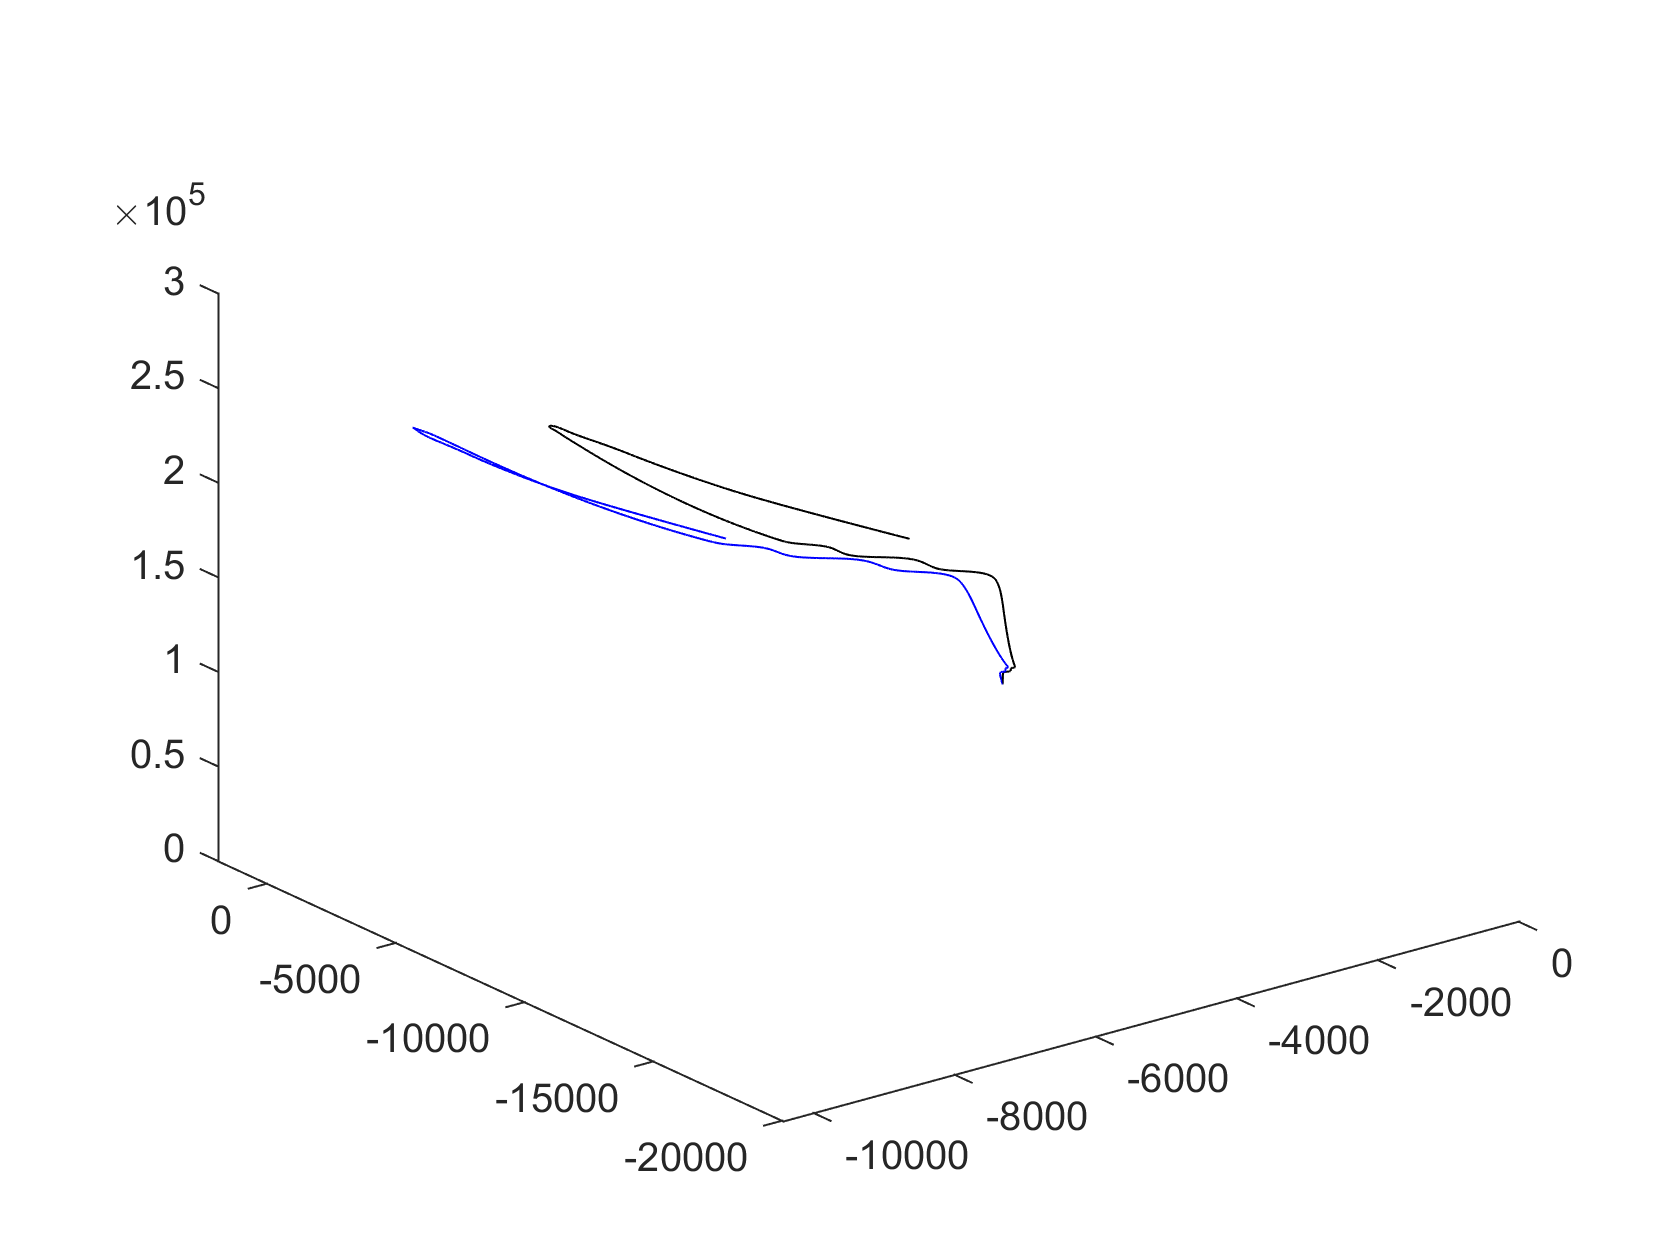


dataLN = table2array(x(:,2:4));

dataWR = table2array(x(:,5:7));

accelLN = cumtrapz(0.01,cumtrapz(0.01,dataLN));
accelWR = cumtrapz(0.01,cumtrapz(0.01,dataWR));

plot3(accelLN(:,1),accelLN(:,2),accelLN(:,3),'-k')
hold on
plot3(accelWR(:,1),accelWR(:,2),accelWR(:,3),'-b')


[d,Z,transform] = procrustes(accelLN, accelWR)

d = 4.6265e-07

Z = 	1.0e+05 *

    0.0000    0.0005    0.0001
    0.0000    0.0005    0.0001
    0.0000    0.0005    0.0001
    0.0000    0.0005    0.0001
    0.0000    0.0005    0.0001
    0.0000    0.0005    0.0001
    0.0000    0.0005    0.0001
    0.0000    0.0005    0.0001
    0.0000    0.0005    0.0001
    0.0000    0.0005    0.0001


transform = struct with fields:
    T: [3×3 double]
    b: 0.9857
    c: [30191×3 double]



orthagonal_rotAndRef = transform.T

orthagonal_rotAndRef =     1.0000   -0.0042   -0.0060
    0.0042    1.0000    0.0081
    0.0059   -0.0081    0.9999


translation = transform.c

translation =     1.5830   49.6786   14.4011
    1.5830   49.6786   14.4011
    1.5830   49.6786   14.4011
    1.5830   49.6786   14.4011
    1.5830   49.6786   14.4011
    1.5830   49.6786   14.4011
    1.5830   49.6786   14.4011
    1.5830   49.6786   14.4011
    1.5830   49.6786   14.4011
    1.5830   49.6786   14.4011


scaling = transform.b

scaling = 0.9857